# Structure of Ships

## Topics

- `struct` and `string` data types

- String formatting

## Create a small structure for testing.

Using Wikipedia's list of [current US Navy ships](https://en.wikipedia.org/wiki/List_of_current_ships_of_the_United_States_Navy), Create a structure array named `ships`  and store at least four entries with the following field names and values (note that there are a few different ways to create and populate a [structure array](https://www.mathworks.com/help/matlab/ref/struct.html)):

- `name`: the Ship name as a string

- `hull`: Hull number as a string

- `class`: Name of the class as a string

- `type`: The listed type as a string

- `year`: Year of commission as a number

clear ships

% I picked the first four from the list.  
% Illustrating two alternative ways to initialize elements.
ships(1).name = "USS Abraham Lincoln";
ships(1).hull = "CVN-72";
ships(1).class = "Nimitz";
ships(1).type = "Aircraft carrier";
ships(1).year = 1989;
ships(2) = struct("name", "USS Alabama", "hull", "SSBN-731", ...
    "class", "Ohio", "type", "Ballistic missile submarine", "year", 1985);
ships(3) = struct("name", "USS Alaska", "hull", "SSBN-732", ...
    "class", "Ohio", "type", "Ballistic missile submarine", "year", 1986);
ships(4) = struct("name", "USS Albany", "hull", "SSN-753", ...
    "class", "Los Angeles", "type", "Attack submarine", "year", 1990);

ships

ships = 1×4 struct array with fields:
    name
    hull
    class
    type
    year


## Finding ships by type

Write a local function to find all the ships of a certain type in the structure.

Input Arguments:

- structure contain ship data as described above [structure array]

- class of vessel to find [string scalar]

Return Values:

- structure that is a sub-set of the ships where each element is the ship name of the desired type.   If there are no ships of the type, then return an empty structure.

Operation:  The function should find ships where the string in the type field contains the user-supplied string.  For example, if the user supplies the string "submarine", the returned structure should contain all the ships for which the type field value contains "submarine", e.g., "Ballistic missile submarine", "Attack submarine", etc.  Bonus if you can make the operation insensensitive to case.

Tips:

- The reason we start with a small dataset, a strucutre with just four elements, is so that you can prototype your function as a script, making it easier to view the output at each step.  Once you have a prototype working you can wrap it in a function and surpress the output.

- The `strfind` and/or `contains` functions will likely be useful.

- You may want to extract the elements of one field of your structure as an array.  You can do this a couple of ways: `horzcat(struct.fieldname)` or just `[struct.fieldname]`.  

Following the idea of incremental development, I find it helpful to first put together prototype script that addresses the challenge in a specific case before generalizing it as a function.  When prototyping as a script we can leave off some of the semicolons to have MATLAB display the output which might help us understand the steps.  There are a few ways to do this, but we'll demonstrate two methods.

Precondition is that we have a `ships` structure array.

**Prototype Script: Method One, Using Interation**.   

% For the prototype, just a fixed string to test with
% This will turn into an input argument when when we turn the script into a
% function.
typestr = "sub";
% Vector of matches were we store the indices of the matching structure
% elements.  Initialize as empty.
match_idx = [];
% Loop through the elements of our structure array
for ii = 1:length(ships)
    % For each element, check if the string in the `type` field contains
    % our `typestr`.  We could write this test equivalently using either
    ship = ships(ii);
    % `strfind` or `contains`.
    % Here I've written both ways to illustrate that either works.
    test1 = strfind(lower(ship.type), lower(typestr)) > 0
    test2 = contains(ship.type, typestr, "IgnoreCase",true)
    % If the the `typestr` is found, append the index of the ships element to our list of matches.
    % You can verify that using either `test1` or `test2` provides the same
    % answer.
    if test1
        match_idx(end+1) = ii;
    end
end


test1 =

  0×0 empty logical array



test2 = logical
   0


test1 = logical
   1


test2 = logical
   1


test1 = logical
   1


test2 = logical
   1


test1 = logical
   1


test2 = logical
   1


subset = ships(match_idx)

subset = 1×3 struct array with fields:
    name
    hull
    class
    type
    year


**Prototype Script: Method Two, Using Array of Strings**

This script achieves the same result, but uses the functionality of of the `contains` command to operate upon an array of strings.

% For the prototype, just a fixed string to test with
% This will turn into an input argument when when we turn the script into a
% function.
typestr = "sub";
% Extract the values from the `type` field as an array of strings. 
types = [ships.type]

types = 1×4 string array
    "Aircraft carrier"    "Ballistic missile submarine"    "Ballistic missile submarine"    "Attack submarine"


% Find all of the string elements that contain the user-defined string.
% Returns an array of the same length as ships with logial values.
matches = contains(types , typestr, "IgnoreCase", true)

matches = 1×4 logical array
   0   1   1   1


% Get the indices for each true value in the matches array
matches_idx = find(matches)

matches_idx =      2     3     4


% Slice the original structure array
subset = ships(matches_idx)

subset = 1×3 struct array with fields:
    name
    hull
    class
    type
    year


**Now we can turn the prototype into a function.**

- add a function signature at the top to take input arguments (original structure and string pattern to match) and output varaiable (the subset of the structure elements were the typestr pattern matches the string value in the `type` field of the structure)

function subset = ships_by_type_contains(ships, typestr)
    % Extract the values from the field as an array of strings. 


subset = 1×2 struct array with fields:
    name
    hull
    class
    type
    year


    %subset = ;
end

## Finding ships by year

Write a function to report all the ships commissioned on-or-after a user-provided year.

Input Arguments:

- structure with the fields defined in above.

- threshold year as a number (aka, double) 

Return Values: None **(Fruitless)**

Operation: Print formatted text to the screen of the ship name and year in **descending order by year **for vessels commissioned on or after the user-provided year.  The formatting is illustrated below.

Example:

If we our structure contains the first four ships from the wikipedia page and the year is 1986, we would expect this output:

### Approach

We could think of this in two parts

- Extracting a subset of the structure array based on a logical comparison of the `year` field with numeric values.  For this we can do something like

year = 1989;
years = [ships.year];
subset = ships(find(years >= year))

- Sorting a structure by field values

I believe it would be within the bounds of ["be reasonable"](https://wiki.nps.edu/display/AE2440/Syllabus+and+Course+Policies) to ask generative AI for "Provide an example of sorting a MATLAB structure array based on one of the fields".  Claude generated...

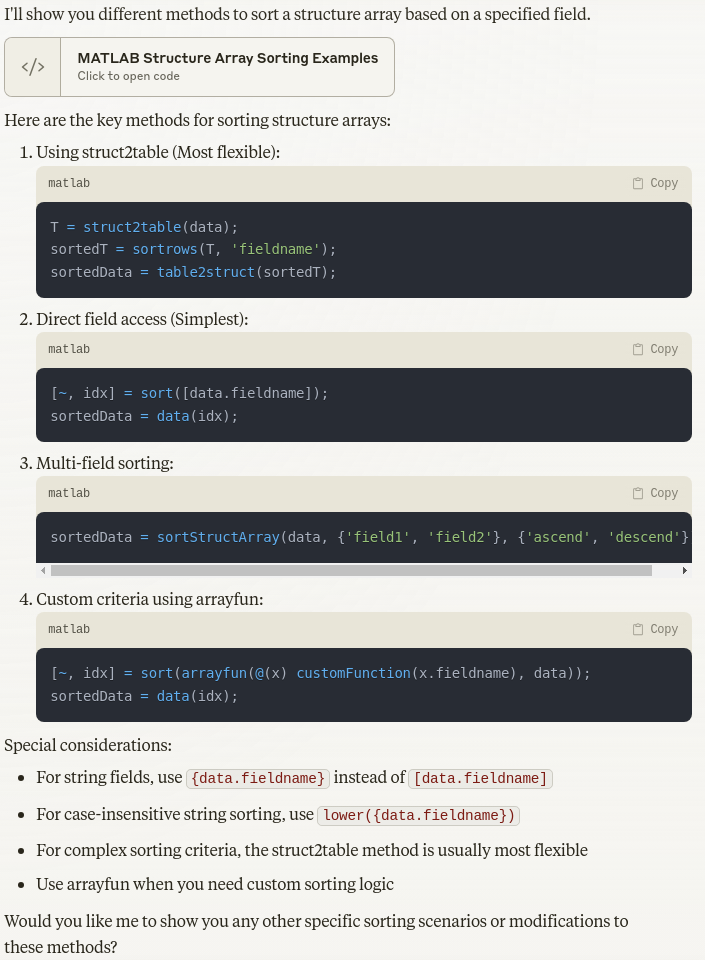

And this code

% Create sample structure array
data = struct();
data(1).name = 'Alice';   data(1).age = 30;   data(1).score = 85.5;
data(2).name = 'Bob';     data(2).age = 25;   data(2).score = 92.0;
data(3).name = 'Charlie'; data(3).age = 35;   data(3).score = 78.3;
data(4).name = 'David';   data(4).age = 28;   data(4).score = 88.7;

Method 1: Using struct2table


data(5).name = 'Eve';     data(5).age = 32;   data(5).score = 95.2;

% Method 1: Using sort with struct2table
fprintf('Method 1: Using struct2table\n')

Sorted by age:


T = struct2table(data);

  5×1 struct array with fields:

    name
    age
    score



sortedT = sortrows(T, 'age');  % Sort by age
sortedData1 = table2struct(sortedT);
disp('Sorted by age:')


Method 2: Using direct field values


disp(sortedData1)

% Method 2: Using sort directly on field values

Sorted by age:


fprintf('\nMethod 2: Using direct field values\n')

  1×5 struct array with fields:

    name
    age
    score



[~, idx] = sort([data.age]);  % Sort by age
sortedData2 = data(idx);
disp('Sorted by age:')
disp(sortedData2)

% Method 3: Custom function for multi-field sorting
function sortedStruct = sortStructArray(structArray, fields, directions)
    % fields: cell array of field names to sort by
    % directions: cell array of 'ascend' or 'descend' for each field
    
    if nargin < 3
        directions = repmat({'ascend'}, size(fields));
    end
    
    % Convert to table for easier sorting
    T = struct2table(structArray);
    
    % Sort using multiple fields
    sortedT = sortrows(T, fields, directions);
    
    % Convert back to structure
    sortedStruct = table2struct(sortedT);


Method 3: Multi-field sorting


end


Sorted by age (ascending) and score (descending):


% Example usage of multi-field sorting

  5×1 struct array with fields:

    name
    age
    score



fprintf('\nMethod 3: Multi-field sorting\n')
sortedData3 = sortStructArray(data, {'age', 'score'}, {'ascend', 'descend'});
disp('Sorted by age (ascending) and score (descending):')


Method 4: Using arrayfun with custom criteria


disp(sortedData3)

% Method 4: Using arrayfun for custom sorting criteria
fprintf('\nMethod 4: Using arrayfun with custom criteria\n')

Sorted by distance from age 30:


% Example: Sort by absolute difference from age 30

  1×5 struct array with fields:

    name
    age
    score



[~, idx] = sort(arrayfun(@(x) abs(x.age - 30), data));
sortedData4 = data(idx);
disp('Sorted by distance from age 30:')


Case-insensitive name sorting:


disp(sortedData4)

% Example of case-insensitive string sorting

Sorted by name (case-insensitive):


fprintf('\nCase-insensitive name sorting:\n')

  1×5 struct array with fields:

    name
    age
    score



[~, idx] = sort(lower({data.name}));
sortedData5 = data(idx);
disp('Sorted by name (case-insensitive):')
disp(sortedData5)

**Which recommended method(s) seem approachable based on what we know so far?**

Write a few simple tests to verify your function.

**What would we expect to get from these tests?**

print_ships_by_year(ships, 1986)

Unrecognized function or variable 'print_ships_by_year'.

print_ships_by_year(ships, 2030)    

Use the function to print the vessels commissioned after the average year in the structure.

**How could we get the average year from our structure array?**

% Your code here.       

## Use the functions on a larger dataset.

The file `ships_data.csv` contains a larger dataset with the information for 116 ships in comma-separated-value (CSV) format.  

#### Download the data

You will need to download the data file using this link: [ships_data.csv](https://raw.githubusercontent.com/bsb808/ae2440/refs/heads/main/assign4/ships_data.csv?token=GHSAT0AAAAAACX7UPEETCKK7FQR2WFB3H4MZYJOCEA)

Depending on your browser settings this may dowload the CSV text file OR you may need to right-click in the browser and use save-as to save with the file name.

Move the file your local working directory. Your working directory is the same directory where you have this live script file saved.  You must also have your MATLAB Command Window in that same working directory.  If you get an error such as "`Unable to find or open 'ships_data.csv'. Check the path and filename or file permissions"`, this issue is probably that you do not have the live script, the CSV data file and the Command Window all in the same folder/directory. 

#### Load the data

You can read the data into a structure with these two commands. (You can just copy the commands to the next Code block.)

% Your code here.       
ships_table = readtable('ships_data.csv', 'TextType','string')
ships = table2struct(ships_table) 

#### Exercise the functions

Answer the following questions with formatted text ouput.

- How many destroyers are in the data?

% Your code here.       

- What is the name of the name and year of the oldest LCS in the data?

- What is the newest?

typestr = "littoral";
lcs = ships_by_type_contains(ships, typestr);
[m, idx] = min([lcs.year]);

- Print all the submarines commissioned after 2000 in descending order by year.

print_ships_by_year(ships_by_type_loop(ships, "littoral"), 1998)